**Q2. a) Using appropriate hypothesis tests, analyse whether the natural logarithm of GBPUSD spot exchange rate from data set 3 is consistent with the random walk model.**

%Task 2a
%Setting default directory
cd('Set location of your default directory');

%Set file location for loading data 3
file_location = 'Your file location\Data set 3';
[spot_price, date_2] = log_pop(file_location, 'XUMAUSS  Bank of England  Database.xlsx', ...
    'XUMAUSS  Bank of England  Datab', 'B2:B283');

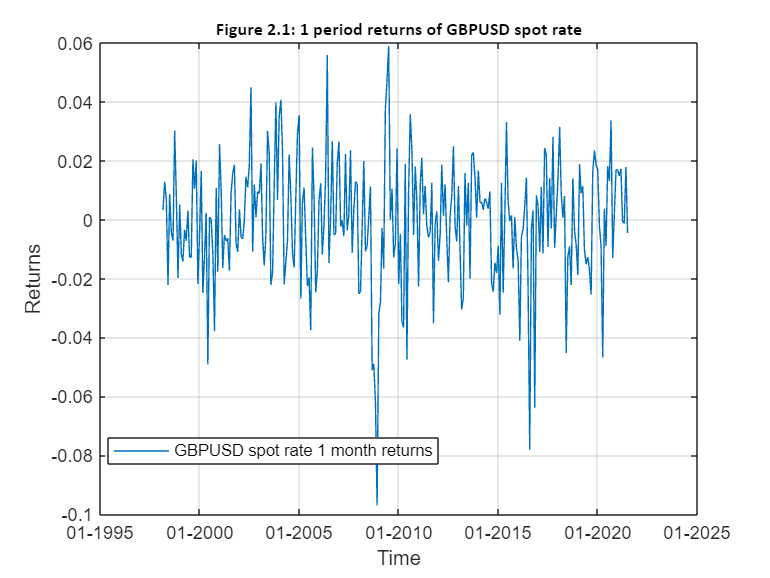



spot_dif = spot_price(2:end,1) - spot_price(1:end-1,1);
plot(date_2(2:end,1),spot_dif);
grid on;
title("Figure 2.1: 1 period returns of GBPUSD spot rate", ...
    FontSize=10,FontName="Calibri"); % Adding a title
legend("GBPUSD spot rate 1 month returns ", Location="best"); % Adding legend
xlabel("Time");
ylabel("Returns");
datetick('x','mm-yyyy') %Add date ticks.

% Saving the current graph
% saveas(gcf,"fig21.jpg"); % Uncomment to save the graph

% Creating an array with first row as headers and next row as its
% corresponding values
adf_rw(1,1) = "p-Value"; adf_rw(1,2) = "t statistic"; 
adf_rw(1,3) = "Critical Value (5%)";
%Compute the DF test with drift.
[df_NHr,adf_rw(2,1),adf_rw(2,2),adf_rw(2,3)] = adftest(spot_price, ...
    model='ARD',test='t1',alpha=0.05);

% Creating an array with first row as headers and next row as its
% corresponding values
adf_rwt(1,1) = "p-Value"; adf_rwt(1,2) = "t statistic"; 
adf_rwt(1,3) = "Critical Value (5%)";
%Compute the DF test with trend.
[df_t_NHr,adf_rwt(2,1),adf_rwt(2,2),adf_rwt(2,3)] = adftest(spot_price, ...
    model='TS',test='t1',alpha=0.05);

% Creating an array with first row as headers and next row as its
% corresponding values
vr_test(1,1) = "p-Value"; vr_test(1,2) = "t statistic"; 
vr_test(1,3) = "Critical Value (5%)"; vr_test(1,4) = "VR ratio";

vr_test = 2×4 string array
    "p-Value"      "t statistic"    "Critical Value (5%)"    "VR ratio"
    "2.696e-05"    "4.1977"         "1.96"                   "1.2509"  


%Compute the VR test with assumption of Homoskedasticity
[vr_NHr,vr_test(2,1),vr_test(2,2),vr_test(2,3),vr_test(2,4)] = vratiotest(spot_price, ...
    period=2, IID=true, alpha=0.05);

% Creating an array with first row as headers and next row as its
% corresponding values
vr_test2(1,1) = "p-Value"; vr_test2(1,2) = "t statistic"; 
vr_test2(1,3) = "Critical Value (5%)"; vr_test2(1,4) = "VR ratio";

vr_test2 = 2×4 string array
    "p-Value"       "t statistic"    "Critical Value (5%)"    "VR ratio"
    "0.00090757"    "3.3177"         "1.96"                   "1.4006"  


%Compute the VR test with assumption of Heteroskedasticity.
[vr_NHr,vr_test2(2,1),vr_test2(2,2),vr_test2(2,3),vr_test2(2,4)] = vratiotest(spot_price, ...
    period=3, IID=false, alpha=0.05);


% Saving all the test results in an excel format
% writematrix(adf_rw,"Task 2 ADF test.xlsx"); %Table 1.2(Uncomment to save)
% writematrix(adf_rwt,"Task 2 ADF test with trend.xlsx"); %Table 1.2(Uncomment to save)
% writematrix(vr_test,"Task 2 VR test 1.xlsx"); %Table 1.2(Uncomment to save)
% writematrix(vr_test2,"Task 2 VR test 2.xlsx"); %Table 1.2(Uncomment to save)

**Q2. (b) Using the natural logarithm of the GBPUSD spot and forward exchange rates from data set 3, test the forward rate unbiasedness (FRU) hypothesis.**

%Task 2b
file_location = 'C:\Users\Krane\Desktop\Matlab assignment\Data set 3';
[frwd_price,~] = log_pop(file_location, 'XUMLDS1  Bank of England  Database.xlsx', ...
    'XUMLDS1  Bank of England  Datab', 'B2:B283');

ds = spot_price(2:end,1)-spot_price(1:end-1,1);
df_s = frwd_price(2:end,1)-spot_price(1:end-1,1);

% Computing Beta, standard error, t-test and sum of squared residuals
%using User defined function cust_fitlm
[beta, se, t_test, ssr] = cust_fitlm(df_s,ds, true);

%Computing Degrees of Freedom
df = size(ds,1) - 2;
%Computing the critical value for the t-tests.
t_crit = tinv(0.975,df);

% T-test for alpha equals to 0
if abs(t_crit)<abs(t_test(1,1))
    fprintf("Null hypothesis is rejected & the estimator is statistically significant");
else
    fprintf("Statistically different and failed to reject null hypothesis");
end

Null hypothesis is rejected & the estimator is statistically significant


% T-test for beta equals to 0
if abs(t_crit)<abs(t_test(2,1))
    fprintf("Null hypothesis is rejected & the estimator is statistically significant");
else
    fprintf("Statistically different and failed to reject null hypothesis");
end

Null hypothesis is rejected & the estimator is statistically significant


% T-test for beta equals to 1
t_test_beta = (beta(2,1)-1)./se(2,1);
if abs(t_crit)<abs(t_test_beta)
    fprintf("Null hypothesis is rejected & the estimator is statistically significant");
else
    fprintf("Statistically different and failed to reject null hypothesis");
end

Statistically different and failed to reject null hypothesis

%F-test for alpha = 0 and beta = 1
q = 2; %Since the number of restricted variables is 2
ssr_r = sum((ds-[ones(size(df_s,1),1) df_s]*[0;1]).^2); %Computing  Ristricted SSR.
f_test = ((ssr_r -ssr)./q)./(ssr./(df));

%Computing the critical value for the F-test.
f_crit = finv(0.95,q,df);

if abs(f_crit)<abs(f_test)
    fprintf("Null hypothesis is rejected & the estimator is statistically significant");
else
    fprintf("Statistically different and failed to reject null hypothesis");
end

Null hypothesis is rejected & the estimator is statistically significant

% Creating array reg to store the regression analysis results
reg(1,2) = "alpha"; reg(2,2) = beta(1,1);
reg(1,3) = "beta"; reg(2,3) = beta(2,1);
reg(1,4) = "SSR"; reg(2,4) = ssr;
reg(2,1) = "Value";
reg(3,1) = "t statistic";
reg(3,2) =  t_test(1,1); 
reg(3,3) = t_test(2,1);
reg(4,1) = "Critical value (5% two-sided)";

reg = 4×4 string array
    <missing>                          "alpha"         "beta"        "SSR"       
    "Value"                            "0.00034785"    "0.99935"     "0.00031859"
    "t statistic"                      "5.4614"        "325.9432"    <missing>   
    "Critical value (5% two-sided)"    "1.9685"        "1.9685"      <missing>   


reg(4,2) = t_crit; reg(4,3) = t_crit;
 
% Saving the regression analysis results in an excel format
% writematrix(reg,"Task 2 reg analysis.xlsx"); %Table 2.5(Uncomment to save)